### Testing shape generation

length_x = 5;
length_y = 1;
posn_rect = [1; 3];
theta = pi/6; % Rads
resolution = 64; % Total points (distributed evenly)
points_rect = generate_rect(length_x, length_y, posn_rect, theta, resolution);

radius = 2;
posn_circle = [-1; -3];

points_circle = generate_circle(radius, posn_circle, resolution);

figure();
hold on

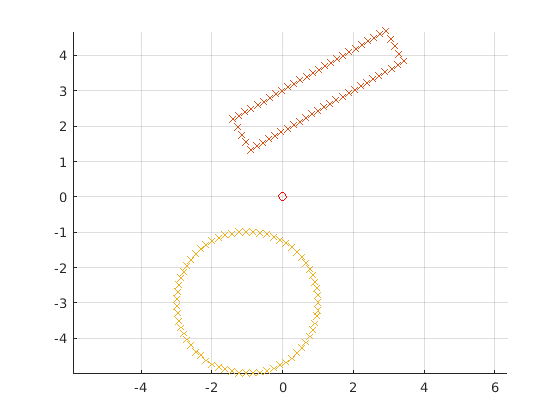


plot(0, 0, 'ro')

scatter(points_rect(1, :), points_rect(2, :), 'x')
scatter(points_circle(1, :), points_circle(2, :), 'x')

grid on
axis equal

### Constructing the gauntlet

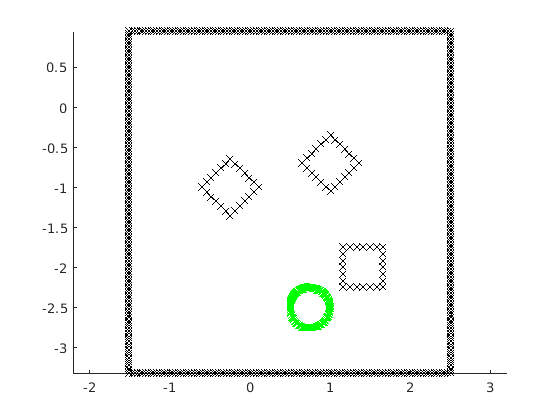

border_res = 500;
obs_res = 30;
bucket_res = 300;


border = generate_rect(4, 4.27, [0.5; -1.185], 0, border_res);
cube_1 = generate_rect(0.5, 0.5, [-0.25; -1], pi/4, obs_res);
cube_2 = generate_rect(0.5, 0.5, [1; -0.7], pi/4, obs_res);
cube_3 = generate_rect(0.5, 0.5, [1.41; -2], 0, obs_res);
sources = [border, cube_1, cube_2, cube_3];

bucket = generate_circle(0.25, [0.75; -2.5], bucket_res);
sinks = bucket;

figure()
hold on
plot(sources(1,:), sources(2,:),'xk')
plot(sinks(1,:), sinks(2,:), 'xg')
axis equal

### Create Potential Field and Gradient Functions

f_potential_sink = @(X, Y, a, b) (log(sqrt((X-a).^2 + (Y-b).^2)));
f_grad_sink = @(X, Y, a, b) (deal( ...
    -(X-a)./((X-a).^2 + (Y-b).^2), ...
    -(Y-b)./((X-a).^2 + (Y-b).^2)...
));

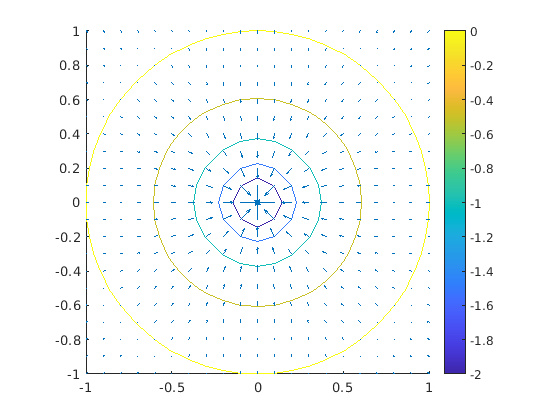

[X, Y] = meshgrid(-1:0.1:1, -1:0.1:1);

a = 0;
b = 0;

Z = f_potential_sink(X, Y, a, b);
[U, V] = f_grad_sink(X, Y, a, b);

figure()
hold on;

contour(X, Y, Z);
quiver(X, Y, U, V);
colorbar

axis equal

### Create Potential Field and Gradient for the Gauntlet

res = 1000;
x = linspace(-2, 3, res);
y = linspace(-3.5, 1.5, res);
[X, Y] = meshgrid(x, y);


[Z_sources, U_sources, V_sources] = calculate_fields(X, Y, sources, -1); % -2 to indicate these are sources

[Z_sinks, U_sinks, V_sinks] = calculate_fields(X, Y, sinks, 1);

Z = Z_sources+Z_sinks;
U = U_sources+U_sinks;
V = V_sources+V_sinks;

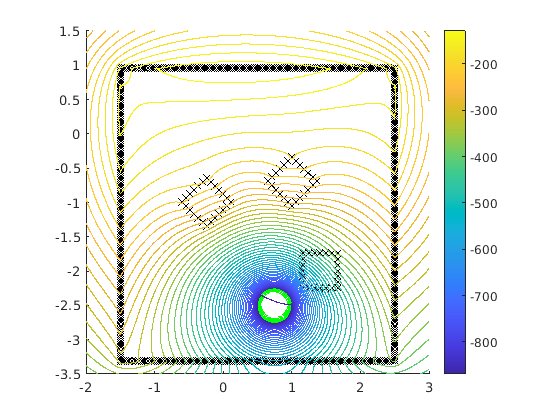

figure()
hold on;    

plot(sources(1,:), sources(2,:),'xk')
plot(sinks(1,:), sinks(2,:), 'xg')
    
contour(X, Y, Z, 50);
colorbar

axis equal

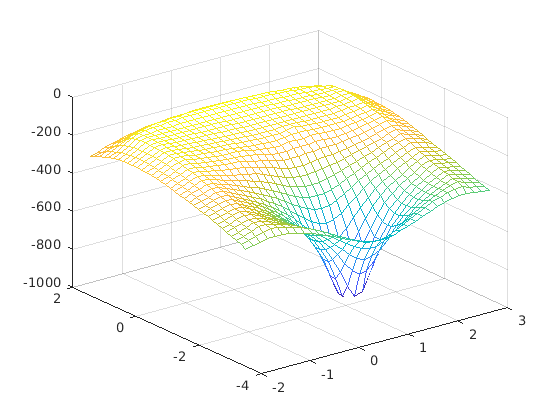

figure()
n = 30;
selection = 1:n:length(X);
mesh(X(selection, selection), Y(selection, selection), Z(selection, selection))

### Finding positions and headings with gradient descent 

%Set up parameters
lambda = 0.3;
delta = 0.9;
max_num = 20;
initial_position = [
    0;
    0;
    1;
    0];
positions = zeros(4,max_num);
positions(:,1) = initial_position;

%Loop to find max_num of points with gradient ascent
for i = 2:max_num
    [z_sinks, gradx_sinks, grady_sinks] = calculate_fields(positions(1,i-1), positions(2,i-1), sinks, 1);
    [z_sources, gradx_sources, grady_sources] = calculate_fields(positions(1,i-1), positions(2,i-1), sources, -1);
    z = z_sinks + z_sources;
    gradx = gradx_sinks + gradx_sources;
    grady = grady_sinks + grady_sources;
    grad_norm = norm([gradx; grady]);
    
    positions(:,i) = [positions(1,i-1) + lambda * gradx / grad_norm;
                      positions(2,i-1) + lambda * grady / grad_norm;
                      gradx/grad_norm;
                      grady/grad_norm];
    lambda = delta * lambda;              
end

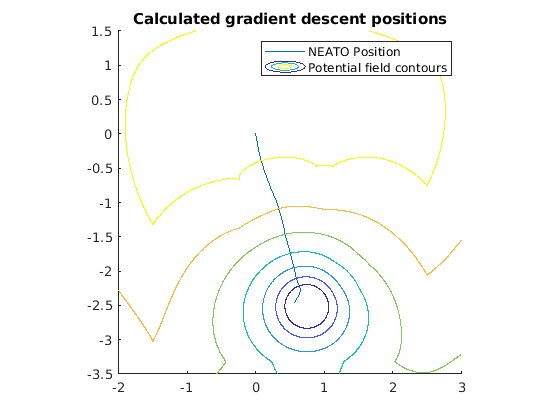

figure()
hold on
plot(positions(1,:),positions(2,:))
contour(X,Y,Z)
title("Calculated gradient descent positions")
legend("NEATO Position","Potential field contours")
axis equal

### Driving the robot

% Put robot in starting position and heading
placeNeato(0,0,1,0);

% Create publisher and subscriber
pubvel = rospublisher('/raw_vel');
sub_bump = rossubscriber('/bump');

% Create corresponding message struct
message = rosmessage(pubvel);  

% Set initial velocity to zero
message.Data = [0, 0]; 
send(pubvel, message);

% Start while loop timing
elapsed = 0;
tic_loop = rostic;

% Parameters
d = 0.235;
step = 1;
angular_wheel_speed = 0.025;
forward_wheel_speed = 0.05;


while rostoc(tic_loop) < 10 || step < max_num
    % Set up this step
    step = step + 1;
    current_location = positions(1:2,step-1);
    
    next_location = positions(1:2,step);
    current_heading = exp(atan2(positions(4,step-1),positions(3,step-1))*1i);
    next_heading = exp(atan2(positions(4,step),positions(3,step))*1i);
   
    % Calculations for changing heading
    quotient = next_heading/current_heading;
    angle_difference = real(log(quotient)/1i);
    omega = 2 * angular_wheel_speed / d;
    v_r = angular_wheel_speed * sign(angle_difference);
    v_l = -angular_wheel_speed * sign(angle_difference);
    heading_time = abs(angle_difference) / omega;
    
    % Set up timer
    tic_ang = rostic;
    
    % Send new velocities
    message.Data = [v_l,v_r];
    send(pubvel,message);
    
    while rostoc(tic_ang) < heading_time
        
    end
    
    % Set end velocity to zero
    message.Data = [0, 0]; 
    send(pubvel, message);
    
    % Calculations for forward movement
    distance = norm(next_location-current_location);
    distance_time = distance / forward_wheel_speed;
    
    % Set up new velocities
    message.Data = [forward_wheel_speed, forward_wheel_speed];
    
    % Set up timer
    tic_forward = rostic;
    
    % Send new velocities
    send(pubvel,message);
    
    while rostoc(tic_forward) < distance_time
        
    end
    
    % Set end velocity to zero
    message.Data = [0, 0]; 
    send(pubvel, message);
    
end

% Set end velocity to zero
message.Data = [0, 0]; 
send(pubvel, message);

### Encoder data

% Load encoder data and variables
encoder_data = readtable("encoder_data.csv");


t_meas = encoder_data.time_seconds_;
l_meas = encoder_data.encoderLeft_meters_;
r_meas = encoder_data.encoderRight_meters_;

% Numerically differentiate the data using Euler discretization
dt_meas = diff(t_meas);
v_l_meas = diff(l_meas) ./ dt_meas;
v_r_meas = diff(r_meas) ./ dt_meas;

% Numerically differentiate the data using Euler discretization
dt_meas = diff(t_meas);
v_l_meas = diff(l_meas) ./ dt_meas;
v_r_meas = diff(r_meas) ./ dt_meas;

% Calculate discrete speed and omega from measured left and right wheel
% speeds
speed_meas = (v_l_meas + v_r_meas) / 2;
omega_meas = (v_r_meas - v_l_meas) / d;
% Numerically integrate omegas to get heading(theta) over time
thetas = cumtrapz(t_meas(2:end), omega_meas);

% Preallocate velocity matrix
vel_meas = NaN(size(speed_meas,1), 2);

% Calculate velocity matrix
for i = 1:size(speed_meas,1)
    % The velocity vector at each point is the velocity in the body frame,
    % which is [speed; 0], rotated by the body->world rotation matrix
    %
    % This gives us the velocity vector in the world frame
    
    theta = thetas(i);
    rot_mat_body_to_world = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    vel_meas(i,:) =  rot_mat_body_to_world * [speed_meas(i); 0];
end

% We can then numerically integrate the velocity vectors to calculate the
% position over time
pos_meas = cumtrapz(t_meas(2:end), vel_meas,1);

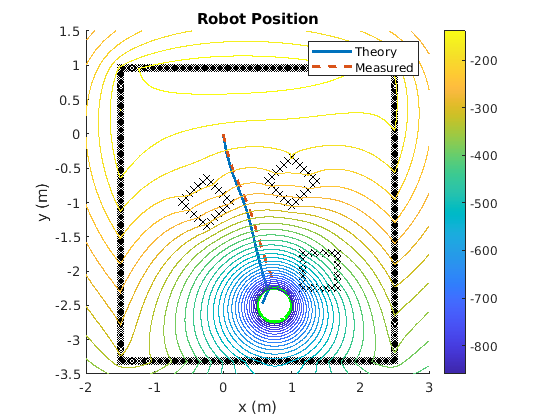

% Plotting
figure()
hold on
plot(positions(1,:), positions(2,:),"-","LineWidth",2)
plot(pos_meas(:,1), pos_meas(:,2), "--","LineWidth",2)
plot(sources(1,:), sources(2,:),'xk')
plot(sinks(1,:), sinks(2,:), 'xg',"MarkerSize",3)
    
contour(X, Y, Z, 30,"LineWidth",0.25);
colorbar

axis equal
xlabel("x (m)")
ylabel("y (m)")
legend("Theory", "Measured")
title("Robot Position")

f_2d_rotmat = @(theta)([cos(theta), -sin(theta); sin(theta), cos(theta)]);
f_rotate_pos_meas = @(theta) (transpose(f_2d_rotmat(theta)*pos_meas'));

pos_meas_rotated = f_rotate_pos_meas(deg2rad(-10));
figure()
hold on;
plot(positions(1,:), positions(2,:),"-")
plot(pos_meas_rotated(:, 1), pos_meas_rotated(:, 2), '--')
axis equal

function points_out = generate_rect(length_x, length_y, position, theta, resolution)
    % Create rect points
    res_x = 0.5 * resolution * length_x / (length_x + length_y);
    res_y = 0.5 * resolution * length_y / (length_x + length_y);
    
    edge_coords_x = length_x * linspace(-0.5, 0.5, res_x);
    edge_coords_y = length_y * linspace(-0.5, 0.5, res_y);
    const_coords_x = length_x * 0.5*ones(size(edge_coords_y));
    const_coords_y = length_y * 0.5*ones(size(edge_coords_x));
    
    
    top_edge = [edge_coords_x; const_coords_y];
    bottom_edge = [edge_coords_x; -const_coords_y];
    
    left_edge = [-const_coords_x; edge_coords_y];
    right_edge = [const_coords_x; edge_coords_y];
    
    points_out = [top_edge, bottom_edge, left_edge, right_edge];
    
    % Rotate rect about center
    rot_mat = [cos(theta) -sin(theta);
               sin(theta)  cos(theta)];
    
    points_out = rot_mat*points_out;
    
    % Translate rect
    points_out = [points_out; ones(1, size(points_out, 2))];
    trans_mat = eye(3);
    trans_mat(1:2, 3) = position;
    
    points_out = trans_mat*points_out;
end

function points_out = generate_circle(radius, position, resolution)
    thetas = linspace(0, 2*pi, resolution);
    
    % Create circle points
    points_out = [radius*cos(thetas);
              radius*sin(thetas);
              ones(size(thetas))];
    
    % Translate circle
    trans_mat = eye(3);
    trans_mat(1:2, 3) = position;
    
    points_out = trans_mat*points_out;
end

function Z = potential_sink(X, Y, a, b)
    Z = log(sqrt((X-a).^2 + (Y-b).^2));
end

function [U, V] = grad_sink(X, Y, a, b)
    U = -(X-a)./((X-a).^2 + (Y-b).^2);
    V = -(Y-b)./((X-a).^2 + (Y-b).^2);
end

function [Z, U, V] = calculate_fields(X, Y, points, coeff)
    Z = zeros(size(X));
    U = zeros(size(X));
    V = zeros(size(X));
    
    for i = 1 : size(points, 2)
        a = points(1, i);
        b = points(2, i);
        
        Z = Z + coeff*potential_sink(X, Y, a, b);
        [U_i, V_i] = grad_sink(X, Y, a, b);
        
        U = U + coeff*U_i;
        V = V + coeff*V_i;
    end
end
